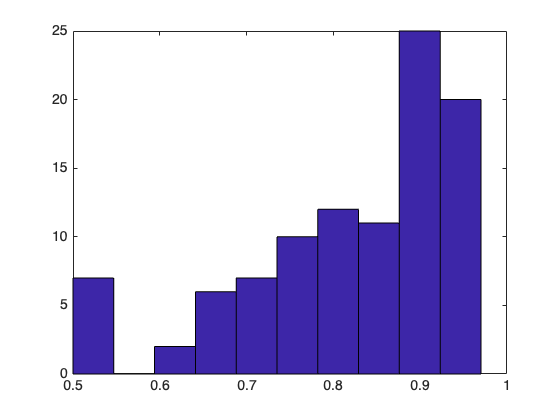

hist(sep_3_iter(:,1))





n=200;
sigma = 1;
K=2;
rounding = 1e-4;
cluster_true = [repelem(1,n/2), repelem(-1,n/2)];
n_iter = 10; 
%%%%%%%%%%%%
sep = 3;
%%%%%%%%%%%%%
s = 10;
M = sqrt(sep^2 / 4 / s);

# p=10, initial accuracy=0.5

p = p_vec(1)

p = 10

rng(2)
sparse_mean = [repelem(1,s), repelem(0,p-s)];
mu_1 =  -M * sparse_mean;
mu_2 =   M * sparse_mean;
mu_1_mat = repmat(mu_1, n/2,1);
mu_2_mat = repmat(mu_2, n/2,1);
    
        
%data generation
x = [ mu_1_mat ; mu_2_mat ] + sigma^2 * randn(n, p);
A = (x * x')/ n; % original affinity matrix (or similarity matrix)
                    %scaling
   
% only first iteration. 
Nov_21_2023_one_threshold_for_two_group_fixed_NaN(x, sigma, K, p, 1, rounding, n, cluster_true);

  breakyes = 1.0,  maxresidual < 1.00e-04
p = 10, acc before thres: 0.500000
1 th thresholding
n_G1=200, n_G2 =0
all observations are clustered into one group
threshold = 2.151324


# p=10, initial accuracy=0.66

p = p_vec(1)

rng(3)
sparse_mean = [repelem(1,s), repelem(0,p-s)];
mu_1 =  -M * sparse_mean;
mu_2 =   M * sparse_mean;
mu_1_mat = repmat(mu_1, n/2,1);
mu_2_mat = repmat(mu_2, n/2,1);
    
        
%data generation
x = [ mu_1_mat ; mu_2_mat ] + sigma^2 * randn(n, p);


A = (x * x')/ n; % original affinity matrix (or similarity matrix)
                    %scaling
   
% only first iteration. 
Nov_21_2023_one_threshold_for_two_group_fixed_NaN(x, sigma, K, p, 3, rounding, n, cluster_true);

  breakyes = 1.0,  maxresidual < 1.00e-04
p = 10, acc before thres: 0.660000
1 th thresholding
n_G1=168, n_G2 =32
absolute difference:

abs_diff =     1.1644    0.9399    1.0371    1.4099    0.5630    1.4773    0.9170    0.6126    0.9603    0.6918


threshold = 0.413912
10 entries survived 


ans =      1     2     3     4     5     6     7     8     9    10


  breakyes = 1.0,  maxresidual < 1.00e-04
After 1th thresholding, acc= 0.660000
2 th thresholding
n_G1=168, n_G2 =32
absolute difference:

abs_diff =     1.1644    0.9399    1.0371    1.4099    0.5630    1.4773    0.9170    0.6126    0.9603    0.6918


threshold = 0.413912
10 entries survived 


ans =      1     2     3     4     5     6     7     8     9    10


  breakyes = 1.0,  maxresidual < 1.00e-04
After 2th thresholding, acc= 0.660000
3 th thresholding
n_G1=168, n_G2 =32
absolute difference:

abs_diff =     1.1644    0.9399    1.0371    1.4099    0.5630    1.4773    0.9170    0.6126    0.9603    0.6918


threshold = 0.413912
10 entries survived 


ans =      1     2     3     4     5     6     7     8     9    10


  breakyes = 1.0,  maxresidual < 1.00e-04
After 3th thresholding, acc= 0.660000


# p=10, initial accuracy=0.66

p = p_vec(2)

p = 536


rng(4)
sparse_mean = [repelem(1,s), repelem(0,p-s)];
mu_1 =  -M * sparse_mean;
mu_2 =   M * sparse_mean;
mu_1_mat = repmat(mu_1, n/2,1);
mu_2_mat = repmat(mu_2, n/2,1);
    
        
%data generation
x = [ mu_1_mat ; mu_2_mat ] + sigma^2 * randn(n, p);


A = (x * x')/ n; % original affinity matrix (or similarity matrix)
                    %scaling
   
% only first iteration. 
[acc, abs_diff, thres] = Nov_21_2023_one_threshold_for_two_group_fixed_NaN(x, sigma, K, p, 2, rounding, n, cluster_true);

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06
p = 536, acc before thres: 0.535000
1 th thresholding
n_G1=193, n_G2 =7
absolute difference:

ans =     0.8117    0.4425    0.9533    0.8631    1.4451    1.2170    0.9917    0.4056    0.1212    0.9225    0.0592    0.0351    0.5087    0.4092    0.3659    0.0475    0.1169    0.3230    0.3450    0.4363    0.0552    0.0353    0.7064    0.0423    0.4899    0.0607    0.1360    0.3747    0.1796    0.1762    0.5428    0.0800    0.4332    0.0779    0.5844    0.2299    0.4448    0.2127    0.1249    0.2509    0.2664    0.0737    0.3517    0.6211    0.6047    0.4892    0.2452    0.3851    0.1384    0.3969


threshold = 1.364034
1 entries survived 


ans = 5

  breakyes = 1.0,  maxresidual < 1.00e-04
After 1th thresholding, acc= 0.585000
2 th thresholding
n_G1=171, n_G2 =29
absolute difference:

ans =     0.4717    0.6005    0.4668    0.4486    1.9532    0.5756    0.3569    0.3653    0.1841    0.1200    0.0327    0.2783    0.1444    0.1984    0.1419    0.1751    0.2215    0.2535    0.0896    0.1478    0.3086    0.1235    0.1506    0.1231    0.3064    0.0946    0.1727    0.3267    0.1378    0.1875    0.2348    0.1043    0.1669    0.0192    0.1079    0.1770    0.3245    0.1618    0.2368    0.0550    0.2632    0.0554    0.5748    0.0770    0.0259    0.1825    0.2363    0.4683    0.0323    0.0362


threshold = 0.711960
1 entries survived 


ans = 5

  breakyes = 1.0,  maxresidual < 1.00e-04
After 2th thresholding, acc= 0.585000


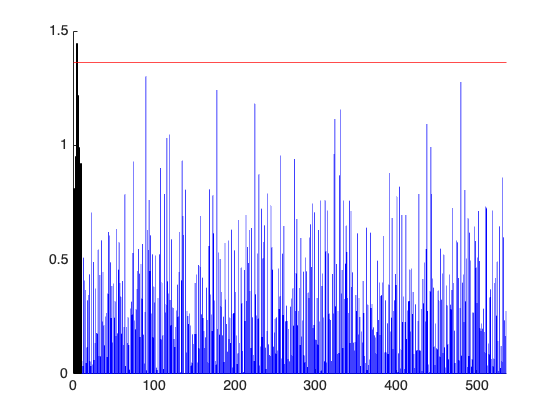

figure;
hold on;
bar(abs_diff(1,:), "blue")
bar(abs_diff(1,1:10), "black")
yline(thres(1), color = "red")
hold off;